%Created by Jacobs Somnic on 20260314
%Latest revision: 
%Purpose: Vaccine simulation for n=2


clc;
clear all; 


%Parameter values
alpha=28;
beta=2; 
lambda=3;
mu=0.5;
delta1=1; 
theta1=0.1;
gamma1=0.012;
delta2=1.3;
theta2=1.3;
gamma2=1;
delta3=1.2;
theta3=1.1; %1.2 works too

parameters=[alpha beta lambda mu delta1 theta1 gamma1 delta2 theta2 gamma2 delta3 theta3];
parameters_EE=[28 2 3 0.5 1 0.1 0.012 1.3 1.3 1 1.2 1.1];
parameters_DFE=[28 0.5 1 0.5 1 0.1 0.012 1.3 1.3 1 1.2 1.1];
%Example of good set
%1. Condition A is satisfied--> parameters=[28 2 3 0.5 1 0.1 0.01 1.3 1.3 1 1.2 1.2];

%Reproduction Number Calculation
R_0=(beta*lambda)/(mu*(mu+delta1+gamma1+theta1))

R_0 = 7.4442



%Constraint calculation
constraints=check_cond_A(parameters);

alpha_min = 17.6726

CONDITION A IS SATISFIED!




%Initial Condition
S0=0.6;I10=0.2;I20=0.1;I30=0.1;R0=0;
y0=[S0;I10;I20;I30;R0];



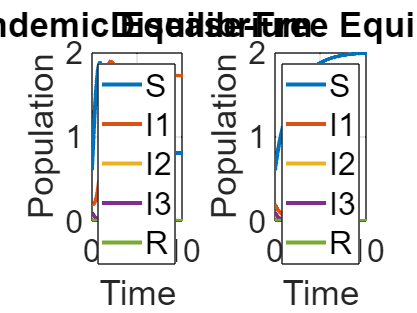

%Normal Plot
tspan=[0 10];


[t_EE,y_EE] = ode45(@(t,y) sirs(t,y,parameters_EE), tspan, y0);
[t_DFE,y_DFE] = ode45(@(t,y) sirs(t,y,parameters_DFE), tspan, y0);

figure('Name','EE vs DFE'); clf

subplot(1,2,1)
plot(t_EE,y_EE,'LineWidth',3)
title('Endemic Equilibrium','FontSize', 27)
xlabel('Time','FontSize', 24)
ylabel('Population','FontSize', 24)
legend('S','I1','I2','I3','R','FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(1,2,2)
plot(t_DFE,y_DFE,'LineWidth',3)
title('Disease-Free Equilibrium','FontSize', 27)
xlabel('Time','FontSize', 24)
ylabel('Population','FontSize',24)
legend('S','I1','I2','I3','R','FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;



%Parameter Study
gamma1_vector=[0.01 0.1 1 5];
col_vec=['r' 'g' 'b' 'm' 'c' 'k'];
figure('Name','Parameter Study'); clf
for i=1:length(gamma1_vector)
    gamma1=gamma1_vector(i);
    parameters=[alpha beta lambda mu delta1 theta1 gamma1 delta2 theta2 gamma2 delta3 theta3];

    [t,y] = ode45(@(t,y) sirs(t,y,parameters), tspan, y0);
    
    subplot(3,2,1)
    h(i)=plot(t,y(:,1),col_vec(i),'LineWidth',3)
    hold on
    
    subplot(3,2,2)
    plot(t,y(:,2),col_vec(i),'LineWidth',3)
    hold on

    subplot(3,2,3)
    plot(t,y(:,3),col_vec(i),'LineWidth',3)
    hold on

    subplot(3,2,4)
    plot(t,y(:,4),col_vec(i),'LineWidth',3)
    hold on

    subplot(3,2,5)
    plot(t,y(:,5),col_vec(i),'LineWidth',3)
    hold on

end

h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1.9322e-04 3.8644e-04 5.7967e-04 7.7289e-04 0.0017 0.0027 0.0037 0.0046 0.0093 0.0140 0.0187 0.0234 0.0295 0.0356 0.0416 0.0477 0.0549 0.0621 0.0693 0.0765 0.0849 0.0933 0.1017 0.1101 0.1199 0.1297 0.1395 0.1492 0.1610 0.1727 … ]
              YData: [0.6000 0.6005 0.6010 0.6014 0.6019 0.6043 0.6067 0.6091 0.6115 0.6231 0.6349 0.6467 0.6586 0.6740 0.6894 0.7047 0.7201 0.7383 0.7565 0.7745 0.7925 0.8133 0.8340 0.8545 0.8748 0.8984 0.9216 0.9447 0.9675 0.9944 1.0210 1.0473 … ]

  Show all properties


h =   1×2 Line array:

    Line    Line


h =   1×3 Line array:

    Line    Line    Line


h =   1×4 Line array:

    Line    Line    Line    Line


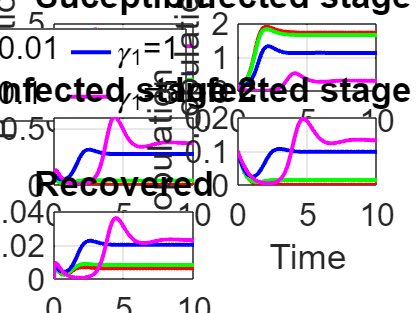


subplot(3,2,1)
title("Suceptible",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,2)
title("Infected stage 1",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,3)
title("Infected stage 2",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,4)
title("Infected stage 3",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,5)
title("Recovered",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;
hold off


subplot(3,2,6)
axis off
legend(h,'\gamma_1=0.01','\gamma_1=0.1','\gamma_1=1','\gamma_1=5','Location','southeast','NumColumns',2,'FontSize', 24)





%Initial Condition Study
col_vec=['r' 'g' 'b' 'm' 'c' 'k'];
S0_vec=[0.8 0.6 0.4 0.2];
I01_vec=[0.2 0.4 0.6 0.8];
 
figure('Name','Initial Condition Study'); clf
%parameters=[alpha beta lambda mu delta1 theta1 gamma1 delta2 theta2 gamma2 delta3 theta3];
parameters_EE=[28 2 3 0.5 1 0.1 0.012 1.3 1.3 1 1.2 1.2];
for i=1:length(S0_vec)

    y0=[S0_vec(i);I01_vec(i);0;0;0];
    [t,y] = ode45(@(t,y) sirs(t,y,parameters_EE), tspan, y0);

    subplot(3,2,1)
    h(i)=plot(t,y(:,1),col_vec(i),'LineWidth',3)
    hold on
    
    subplot(3,2,2)
    plot(t,y(:,2),col_vec(i),'LineWidth',3)
    hold on

    subplot(3,2,3)
    plot(t,y(:,3),col_vec(i),'LineWidth',3)
    hold on

    subplot(3,2,4)
    plot(t,y(:,4),col_vec(i),'LineWidth',3)
    hold on

    subplot(3,2,5)
    plot(t,y(:,5),col_vec(i),'LineWidth',3)
    hold on

end

h =   1×4 Line array:

    Line    Line    Line    Line


h =   1×4 Line array:

    Line    Line    Line    Line


h =   1×4 Line array:

    Line    Line    Line    Line


h =   1×4 Line array:

    Line    Line    Line    Line


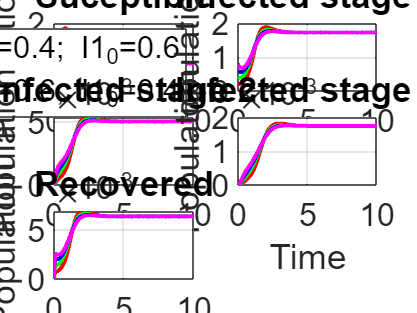


subplot(3,2,1)
title("Suceptible",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,2)
title("Infected stage 1",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,3)
title("Infected stage 2",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,4)
title("Infected stage 3",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,5)
title("Recovered",'FontSize', 27)
xlabel("Time",'FontSize', 24)
ylabel("Population",'FontSize', 24)
grid on
ax=gca;
ax.FontSize=24;

subplot(3,2,6)
axis off
legend(h,'S_0=0.8; I1_0=0.2','S_0=0.6; I1_0=0.4','S_0=0.4; I1_0=0.6','S_0=0.6; I1_0=0.4','Location','southeast','NumColumns',2,'FontSize', 23)

function dydt = sirs(t,y,parameters)
    alpha=parameters(1);
    beta=parameters(2);
    lambda=parameters(3);
    mu=parameters(4);
    delta1=parameters(5); 
    theta1=parameters(6);
    gamma1=parameters(7);
    delta2=parameters(8);
    theta2=parameters(9);
    gamma2=parameters(10);
    delta3=parameters(11);
    theta3=parameters(12);
    

    S=y(1);
    I1=y(2);
    I2=y(3);
    I3=y(4);
    R=y(5);

    dS=lambda+alpha*R-mu*S-beta*S*I1;
    dI1=beta*S*I1-(mu+delta1+gamma1+theta1)*I1;
    dI2=gamma1*I1-(mu+delta2++gamma2+theta2)*I2;
    dI3=gamma2*I2-(mu+delta3+theta3)*I3;
    dR=theta1*I1+theta2*I2+theta3*I3-(alpha+mu)*R;

    dydt = [dS; dI1; dI2;dI3; dR];
end

function condition_A=check_cond_A(parameters)
    
    alpha=parameters(1);
    beta=parameters(2);
    lambda=parameters(3);
    mu=parameters(4);
    delta1=parameters(5); 
    theta1=parameters(6);
    gamma1=parameters(7);
    delta2=parameters(8);
    theta2=parameters(9);
    gamma2=parameters(10);
    delta3=parameters(11);
    theta3=parameters(12);

    b1 = alpha*( ...
    gamma1^2*(gamma2*(delta3 + 2*mu) + (delta2 + 2*mu)*(delta3 + theta3 + 2*mu)) ...
    + gamma1*( ...
        gamma2*(delta3*(theta1 + 2*mu) + delta1*(delta3 - theta2 + theta3 + 2*mu) + 2*mu*(theta1 + theta3 + 2*mu)) ...
        + (delta2*(theta1 + 2*mu) + 2*mu*(theta1 + theta2 + 2*mu))*(delta3 + theta3 + 2*mu) ...
        + delta1*(delta2 + theta2 + 2*mu)*(delta3 - theta2 + theta3 + 2*mu) ...
    ) ...
    - theta1*(gamma2 + delta2 + theta2 + 2*mu)*(gamma2*delta1 + delta1*(delta2 + theta2 + 2*mu) - 2*mu*(delta3 + theta3 + 2*mu)) ...
    + (gamma2 + delta2 + theta2 + 2*mu)*( ...
        gamma1^2*(gamma2*(delta3 + 2*mu) + (delta2 + 2*mu)*(delta3 + theta3 + 2*mu)) ...
        + gamma1*( ...
            gamma2*(delta3*(theta1 + 2*mu) + delta1*(delta3 + 2*mu) + 2*mu*(theta1 + theta3 + 2*mu)) ...
            + (delta2*(theta1 + 2*mu) + delta1*(delta2 + 2*mu) + 2*mu*(theta1 + theta2 + 2*mu))*(delta3 + theta3 + 2*mu) ...
        ) ...
        + 2*theta1*mu*(delta3 + theta3 + 2*mu)*(gamma2 + delta2 + theta2 + 2*mu) ...
    ) ...
    );
    
    b2 = alpha*( ...
        alpha*delta1*theta1*(delta3*theta2 - delta2*theta3 + 2*(theta2 - theta3)*mu) ...
        + theta1*( ...
            delta1*( ...
                gamma2*delta3*theta3 ...
                + gamma2*theta3*(-delta2 - theta2 + theta3) ...
                - 4*delta2*theta3*mu ...
                + 2*delta3*theta2*(theta3 + 2*mu) ...
                + delta3^2*theta2 ...
                - delta2^2*theta3 ...
                - 2*delta2*theta2*theta3 ...
                + 4*theta2*mu^2 ...
                - 4*theta3*mu^2 ...
                + theta2*theta3^2 ...
                - theta2^2*theta3 ...
            ) ...
            - 2*(theta2 - theta3)*mu*(delta3 + theta3 + 2*mu)*(gamma2 + delta2 + theta2 + 2*mu) ...
        ) ...
        - gamma1^2*(theta2 - theta3)*(gamma2*(delta3 + 2*mu) + (delta2 + 2*mu)*(delta3 + theta3 + 2*mu)) ...
        + gamma1*( ...
            -gamma2*(theta2 - theta3)*(delta3*(theta1 + 2*mu) + delta1*(delta3 + theta3 + 2*mu) + 2*mu*(theta1 + theta3 + 2*mu)) ...
            - (theta2 - theta3)*(delta2*(theta1 + 2*mu) + 2*mu*(theta1 + theta2 + 2*mu))*(delta3 + theta3 + 2*mu) ...
            + delta1*( ...
                delta3*(2*theta3*mu + theta2*(theta3 - 2*mu)) ...
                + delta2*(delta3*(theta3 - theta2) - 2*theta2*(theta3 + mu) + theta3*(theta3 + 2*mu)) ...
                - (theta2 - theta3)*(2*mu*(theta3 + 2*mu) + theta2*theta3) ...
            ) ...
        ) ...
    );
    
    b3 = (delta3*theta2 - delta2*theta3 + 2*(theta2 - theta3)*mu)*( ...
        gamma1^2*(gamma2*(delta3 + 2*mu) + (delta2 + 2*mu)*(delta3 + theta3 + 2*mu)) ...
        + gamma1*( ...
            gamma2*(delta3*(theta1 + 2*mu) + delta1*(delta3 + 2*mu) + 2*mu*(theta1 + theta3 + 2*mu)) ...
            + (delta2*(theta1 + 2*mu) + delta1*(delta2 + 2*mu) + 2*mu*(theta1 + theta2 + 2*mu)) ...
              *(delta3 + theta3 + 2*mu) ...
        ) ...
        + 2*theta1*mu*(delta3 + theta3 + 2*mu)*(gamma2 + delta2 + theta2 + 2*mu) ...
    );
    
    b4 = gamma1*(theta1*(-alpha + delta2 + theta2) + gamma1*theta2)*( ...
        -alpha*( ...
            4*mu^2*(gamma1 + delta1 + theta1) ...
            + 2*mu*(gamma1 + delta1 + theta1)*(gamma2 + 2*delta2 + delta3 + theta3) ...
            + gamma2*delta2*theta1 ...
            + gamma2*delta3*theta1 ...
            - gamma2*delta1*theta2 ...
            + gamma1*delta2*theta2 ...
            + gamma2*delta1*theta3 ...
            + gamma1*delta2*theta3 ...
            + gamma1*delta2^2 ...
            + gamma1*gamma2*delta2 ...
            + gamma2*delta1*delta2 ...
            + gamma1*gamma2*delta3 ...
            + gamma2*delta1*delta3 ...
            + gamma1*delta2*delta3 ...
            - delta1*theta2^2 ...
            + delta2^2*theta1 ...
            + delta2*delta3*theta1 ...
            + delta1*delta3*theta2 ...
            + delta2*theta1*theta2 ...
            + delta1*delta2*theta3 ...
            + delta2*theta1*theta3 ...
            + delta1*theta2*theta3 ...
            + delta1*delta2^2 ...
            + delta1*delta2*delta3 ...
        ) ...
        - (gamma1 + delta1 + theta1)*(gamma2 + delta2 + theta2 + 2*mu)*( ...
            gamma2*(delta2 + delta3 + 2*mu) ...
            + delta2*(delta3 + theta2 + theta3 + 4*mu) ...
            + 2*mu*(delta3 + theta3 + 2*mu) ...
            + delta2^2 ...
        ) ...
        - (gamma2 + delta2 + theta2 + 2*mu)*( ...
            -alpha*delta1*theta1 ...
            + 2*mu*(gamma1 + theta1)*(delta3 + theta3) ...
            - gamma1*delta2*theta1 ...
            - gamma1^2*delta2 ...
            - gamma1*delta1*delta2 ...
            + 4*mu^2*(gamma1 + theta1) ...
        )*( ...
            alpha*(2*gamma1*theta2 + theta1*(delta2 + delta3 + theta2 + theta3 + 2*mu)) ...
            + 2*mu*(2*gamma1*theta2 + theta1*(2*delta2 + delta3 + 2*theta2 + theta3)) ...
            + gamma2*(gamma1*(theta2 + theta3) + theta1*(delta2 + delta3 + theta2 + theta3 + 2*mu)) ...
            + (delta2 + delta3 + theta2 + theta3)*(theta2*(gamma1 + theta1) + delta2*theta1) ...
            + 4*theta1*mu^2 ...
        ) ...
    );
    
    alpha_min=b1/(alpha*delta1*theta1*(gamma2+delta2+theta2+2*mu))
    
    %CONDITION A

    c_A1= theta2 > theta3*(2*mu+delta2)/(2*mu+delta3);
    c_A2= theta2 > theta3*(alpha+2*mu+delta2)/(alpha+2*mu+delta3);
    c_A3= alpha>alpha_min;
    c_A4=b2>b3;
    c_A5=b4>0;

    condition_A=[c_A1 c_A2 c_A3 c_A4 c_A5];
    
    if condition_A==[1 1 1 1 1]
        disp("CONDITION A IS SATISFIED!")
    else
        disp("CONDITION A IS NOT SATISFIED!")
    end

end



